# OFDM Dati

## System Parameters

Select the system parameters from a set of allowed values. These parameters are transmitted within the frame header and decoded by the receiver. The entries are representative of typical LTE, WLAN, and 5G NR transmission parameters. More entries may be added as desired, taking note that most parameters have interdependencies on other parameters.

BWIndex = {FFT length, CP length, number of occupied subcarriers, subcarrier spacing, pilot subcarrier spacing, channel BW}:

- 1 = {128, 32, 72, 15e3, 9, 1.4e6}

- 2 = {256, 64, 180, 15e3, 20, 3e6}

- 3 = {512, 128, 300, 15e3, 20, 5e6}

- 4 = {1024, 256, 600, 15e3, 20, 10e6} (default)

- 5 = {2048, 512, 1200, 15e3, 24, 20e6 }

- 6 = {128, 32, 112, 312.5e3, 14, 35.6e6}

- 7 = {4096, 1024, 3276, 30e3, 36, 98.28e6}

Modulation order for all data subcarriers:

- 2 = BPSK

- 4 = QPSK

- 16 = 16-QAM

- 64 = 64-QAM (default)

- 256 = 256-QAM

- 1024 = 1024-QAM

Code rate:

- 0 = 1/2 (default)

- 1 = 2/3

- 2 = 3/4

- 3 = 5/6

Several controls are available to enable or disable receiver impairments and scopes for transceiver visualization. It is recommended that visualizations be disabled for long simulations and/or simulations over multiple SNRs. Controls are also available to enable or disable certain receiver algorithms.

Change the output verbosity to control the diagnostic output text. The "`Low`" setting suppresses diagnostic output during frame processing. The "`High`" setting enables all output.

% Clear persistent state variables and buffers, and close all figures
clear; close all; clc;
load svm_model.mat SVMModel

userParam = struct( ...
    'BWIndex',          3, ...   % Index corresponding to desired bandwidth
    'modOrder',         64, ...   % Subcarrier constellation modulation order
    'codeRateIndex',    3, ...   % Code rate index corresponding to desired rate
    'numSymPerFrame',   15, ...   % Number of OFDM symbols per frame
    'numFrames',        20, ...   % Number of frames to be generated for simulation (12-500)
    'fc',               2410000000, ...   % Carrier frequency (Hz)
    'enableFading',     true                 , ...   % Enable/disable channel fading
    'chanVisual',       "Off", ...   % Channel fading visualization option
    'enableCFO',        true                 , ...   % Enable/disable carrier frequency offset compensation
    'enableCPE',        true                 , ...   % Enable/disable common phase error compensation
    'enableScopes',     false                 , ...   % Enable/disable scopes
    'verbosity',        0);      % Diagnostic output verbosity
epochs = 10;

## Mobile Environment and Impairments

SNRdBvect = 0:1:25; % SNR in dB
v_vect     = 0:0.5:2; % mobile velocity (km/h)     
foff_vect  = 0:0.25:3; % frequency offset (ppm)
fadingPathDelays =  [0 0.1e-6 0.3e-6];
fadingPathGains  =  [0 8 -9];

%modList = [2, 4, 16, 64, 256, 1024];
modList = [2, 4, 16, 64];
results = zeros(epochs,6);
class = zeros(epochs, 1);

## Initialize States and Process Data Frames

Inizializzazione dei parametri di SNR, velocità, modulazione, code rate, CFO, dealys e gains del canale in maniera casuale

for ii = 1:epochs    
    clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMChannel helperOFDMFrequencyOffset
    close all;
    SNRdB = SNRdBvect(randi(26));
    codeRateIndex = randi([0,3]);
    indexMod = randi(3);
    modType = modList(indexMod);
    BERResults = 0; 
    v = v_vect(randi(length(v_vect)));
    foff = foff_vect(randi(length(foff_vect)))
    delay = rand(1,2) * 1e-6;
    
    fadingPathGains = [0 randi([-9, 9],1,2)];
    fadingPathDelays = [0, delay];
    userParam.codeRateIndex = codeRateIndex; 
    userParam.modOrder = modType;
    

foff = 2.5000

foff = 1.5000

foff = 3

foff = 2.7500

foff = 2

foff = 0.2500

foff = 1.5000

foff = 1.5000

foff = 1.7500

foff = 1.5000

Inizializzazione dei parametri per la comunicazione OFDM

    %Populate Parameter Structure
    [sysParam, txParam] = helperOFDMSetParameters(userParam);
    
    [BWstruct,codeParam] = helperOFDMGetTables(userParam.BWIndex,userParam.codeRateIndex);
    codeRate = codeParam.codeRate; % Coding rate
    
    %fprintf('\nTransmitting at %d MHz with an occupied bandwidth of %d MHz\n', ...
    % sysParam.fc/1e6,sysParam.scs*sysParam.usedSubCarr/1e6);

    % Calculate fading channel impairments
    KPH_TO_MPS = (1000/3600);
    fsamp = sysParam.scs*sysParam.FFTLen;       % sample rate of signal
    T = (sysParam.FFTLen+sysParam.CPLen)/fsamp; % symbol duration (s)
    fmax = v * KPH_TO_MPS * sysParam.fc / physconst('LightSpeed');  % Maximum Doppler shift of diffuse components (Hz)
    % Set up scopes
    if userParam.enableScopes
    % Set up constellation diagram object
        refConstHeader = qammod(0:1,2,UnitAveragePower=true); % header is always BPSK
        refConstData   = qammod(0:txParam.modOrder-1,txParam.modOrder,UnitAveragePower=true);

        constDiag = comm.ConstellationDiagram(2, ...
            "ChannelNames",{'Header','Data'}, ...
            "ReferenceConstellation",{refConstHeader,refConstData}, ...
            "ShowLegend",true, ...
            "EnableMeasurements",true);
        % Set up spectrum analyzer visualization object
        sa = spectrumAnalyzer( ...
            'Name',             'Signal Spectra', ...
            'Title',            'Transmitted and Received Signal', ...
            'SpectrumType',     'Power', ...
            'FrequencySpan',    'Full', ...
            'SampleRate',       fsamp, ...
            'ShowLegend',       true, ...
            'Position',         [100 600 800 500], ...
            'ChannelNames',     {'Transmitted','Received'});
    end
    

    %initialization of Rx and Tx
    txObj = helperOFDMTxInit(sysParam);
    rxObj = helperOFDMRxInit(sysParam);

    % Configure the channel
    chanParam = struct( ...
        'SNR',       SNRdB, ...
        'foff',      foff, ...       % normalized frequency offset (ppm)
        'doppler',   fmax*T, ...     % normalized Doppler frequency
        'pathDelay', fadingPathDelays, ...
        'pathGain',  fadingPathGains);
    %fprintf('Configuring the fading AWGN channel at %d dB SNR and %d kph...\n', SNRdB, v);



Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.........


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.........


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.........

.........
Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.


.....................


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.........

.....................


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.........


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.........

.....................

    sysParam.txDataBits = []; % clear tx data buffer

    sysParam.timingAdvance = (sysParam.FFTLen + sysParam.CPLen) * ...
        sysParam.numSymPerFrame; % set sample buffer timing advance
    
    % Instantiate an ErrorRate object to cumulatively track BER
    errorRate = comm.ErrorRate();

    % fprintf('Transmitting %d frames with transport block size of %d bits per frame...\n', ...
    %     sysParam.numFrames,sysParam.trBlkSize);
    % fprintf('Searching for synchronization symbol...');
    
    % Loop through all frames. Generate one extra frame to obtain the
    % reference symbol for channel estimates of the last frame.
    for frameNum = 1:sysParam.numFrames+1
        sysParam.frameNum = frameNum;

## Payload Generation

User data is packed into a transport block, which is transmitted once per frame. The size of the transport block depends on the number of active subcarriers, number of pilot subcarriers that occupy active subcarriers, modulation order, coding rate, CRC length, encoder constraint length, and number of data symbols per frame.

Randomly generated data is used to pack the transport blocks, but custom data can be sent if desired. The data must be split into transport blocks, with the last block padded with zeros if necessary. 

        % Generate random data to transmit. Replace with user data if desired.

Simulation completed at 19 SNR: BER = 0, FER = 0


Simulation completed at 24 SNR: BER = 0, FER = 0


Simulation completed at 16 SNR: BER = 2.721472e-01, FER = 1


Simulation completed at 9 SNR: Base station not detected.


Simulation completed at 2 SNR: Base station not detected.


Simulation completed at 2 SNR: BER = 5.947071e-04, FER = 2.222222e-01


Simulation completed at 8 SNR: Base station not detected.


Simulation completed at 20 SNR: BER = 2.611043e-03, FER = 1


Simulation completed at 16 SNR: BER = 0, FER = 0


Simulation completed at 2 SNR: Base station not detected.


        txParam.txDataBits  = randi([0 1],sysParam.trBlkSize,1);

results =    19.0000         0         0   18.9376   16.0000    0.5000
   24.0000         0         0   11.6982   16.0000    0.6667
   16.0000    0.2721    1.0000   19.4535   16.0000    0.7500
    9.0000    0.5000    1.0000   16.0341   16.0000    0.8333
    2.0000    0.5000    1.0000         0   16.0000    0.7500
    2.0000    0.0006    0.2222    4.0686    2.0000    0.6667
    8.0000    0.5000    1.0000         0    2.0000    0.8333
   20.0000    0.0026    1.0000    7.3124   16.0000    0.8333
   16.0000         0         0   13.1786    2.0000    0.6667
    2.0000    0.5000    1.0000         0    2.0000    0.5000


class =      2
     2
     0
     0
     0
     0
     0
     1
     2
     0


        % Store data bits for BER calculations
        sysParam.txDataBits = [sysParam.txDataBits; txParam.txDataBits];
        sysParam.txDataBits = sysParam.txDataBits(max(1,end-2*sysParam.trBlkSize):end);

## Transmitter Processing

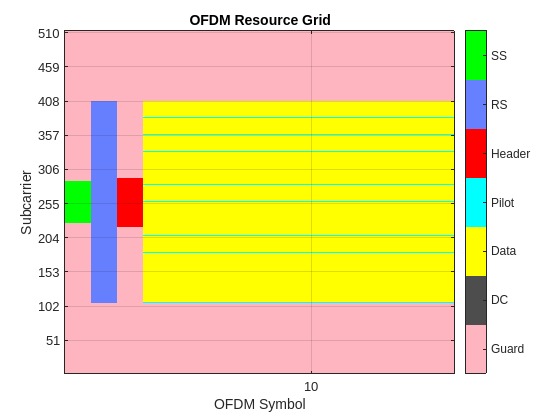

        % Transmit data
        [txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);

## Apply Channel and Hardware Impairments

        % Process one frame of samples through channel
        chanOut = helperOFDMChannel(txOut,chanParam,sysParam, BWstruct);

## Channel Visualization

Use the `spectrumAnalyzer` function to visualize the received spectrum after fading and noise are added to the transmitted signal. As the simulation runs, you can see how the received signal constellation is negatively affected by the spectral nulls caused by multipath fading.

        % if userParam.enableScopes    
        %     sa(txOut,chanOut);
        % end

## Receiver Processing

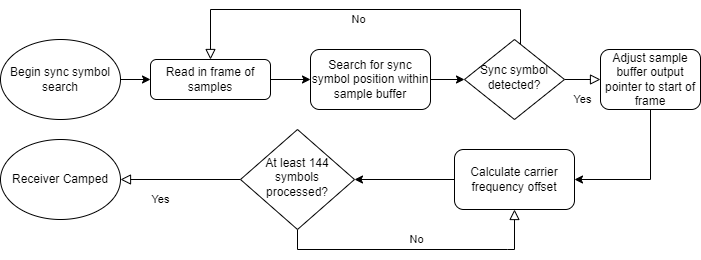

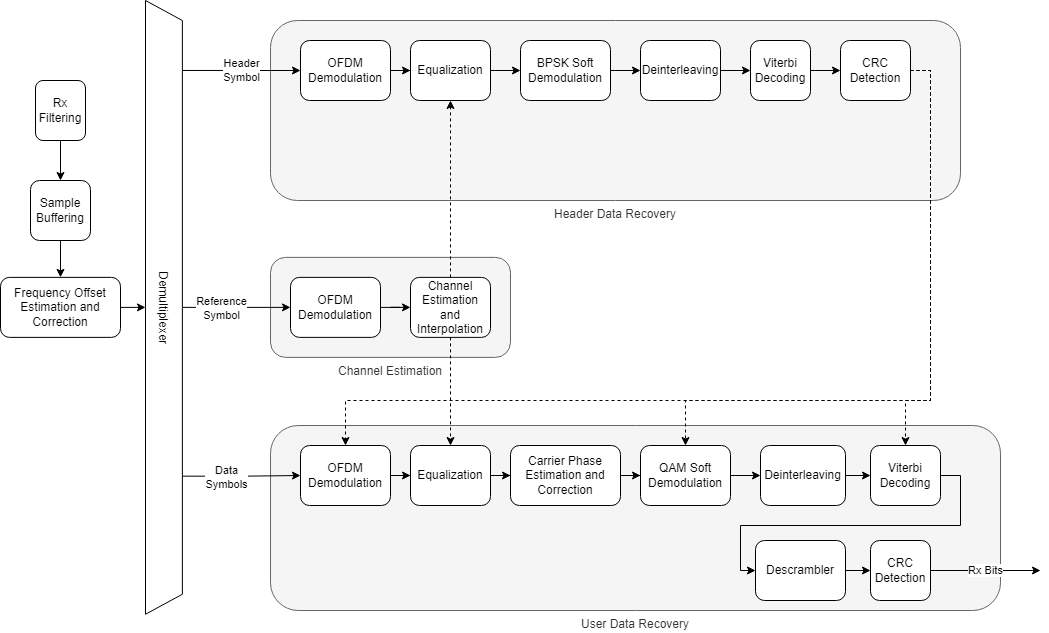

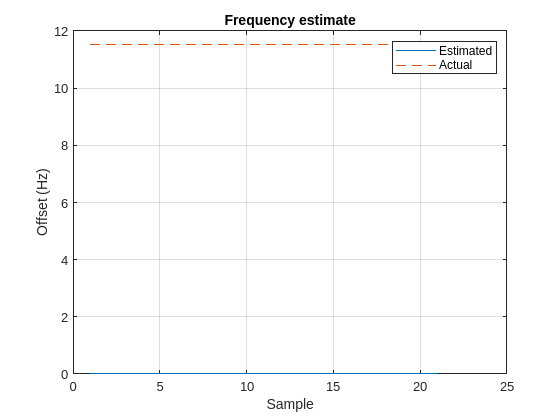

        % Run the receiver front-end
        rxIn = helperOFDMRxFrontEnd(chanOut,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);

        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected    
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % system object
            BER = errorRate(...
                sysParam.txDataBits(end-(2*sysParam.trBlkSize)+(1:sysParam.trBlkSize)), ...
                rxDataBits);
        end


## Receiver Performance Visualization

Use the `comm.ConstellationDiagram` object to display the header constellation and data constellation in one plot. By varying the channel impairments, you can visualize the noise after receiver impairment compensation for all subcarriers superimposed on the plot. EVM and MER can be measured with respect to the reference constellation for each data modulation.

        if isConnected && userParam.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                      complex(rxDiagnostics.rxConstellationData(:)));
        end
    end
     % frame loop

## Clear Simulation and Compute Statistics

Following frame processing, clear out state information stored in persistent variables with the `clear` command. Accumulated bit error rate and frame error rate statistics are calculated and displayed at the simulated SNR. The simulation loads the next SNR and executes another run.

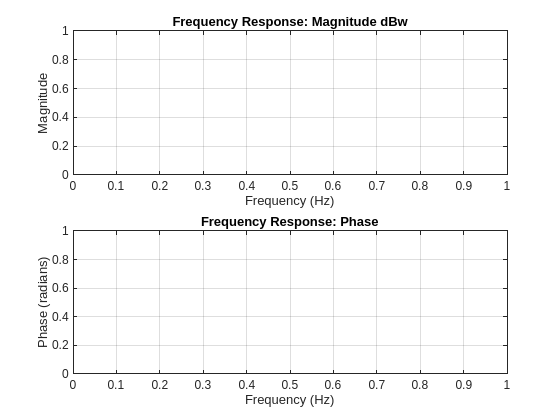

    % Clear out the |persistent| variables for the sync detection flag and
    % camped flag
    clear helperOFDMRx;
    clear helperOFDMRxSearch;

    % Compute data diagnostics
    if isConnected
        FER = sum(rxDiagnostics.dataCRCErrorFlag) / length(rxDiagnostics.dataCRCErrorFlag);
        fprintf('Simulation completed at %d SNR: BER = %d, FER = %d\n',SNRdB,BER(1),FER);
        BERResults = BER(1);
    else
        fprintf('Simulation completed at %d SNR: Base station not detected.\n',SNRdB);
        fprintf('\n');
        FER = 1;
        BERResults = 0.5; % default to high BER for plotting purposes
    end


    % Release object to reconfigure for the next simulation run
    release(errorRate);
    %fprintf('SNRdb =%d  Mod = %d  CodeRate= %d \n', SNRdB, modType, codeRateIndex);
    estCFO = mean(rxDiagnostics.estCFO*sysParam.scs);
    results(ii,:) = [SNRdB, BERResults, FER, estCFO, modType, codeRate];
    class(ii) = helperPredictionSVM(results(ii,1), results(ii,2), SVMModel);
end
results
class
% nomeFile = 'results2.csv';

% % Nomi delle feature
% nomiFeature = {'SNR', 'BER', 'FER', 'CFO', 'MOD','CODERATE',};
% 
% % Apertura del file
% fid = fopen(nomeFile, 'w');
% 
% % Scrittura dell'intestazione
% fprintf(fid, '%s,%s,%s,%s,%s\n', nomiFeature{1}, nomiFeature{2}, nomiFeature{3}, nomiFeature{4}, nomiFeature{5}, nomiFeature{6});
% 
% % Chiusura del file (importante chiudere prima di usare writematrix)
% fclose(fid);

% Scrittura dei dati con writematrix (aggiungendo l'intestazione prima)
% writematrix(results, nomeFile, 'Delimiter', ',', 'QuoteStrings', true, 'WriteMode', 'append');
% 
% disp(['File CSV "' nomeFile '" salvato con successo.']);

## Diagnostics

A diagnostic structure captures various parameters for analysis during the simulation. Receiver performance can be recorded and plotted, such as the last frame's frequency offset tracking and channel estimation tracking. Error metrics like BER and FER/BLER can also be calculated and displayed.

% Plot the transmission grid
helperOFDMPlotResourceGrid(txGrid,sysParam);

% Plot the frequency offset estimator output
figure;
plot(rxDiagnostics.estCFO*sysParam.scs);
hold on;
plot(foff*fsamp*ones(length(rxDiagnostics.estCFO),1)/1e6,'--');
title('Frequency estimate');
xlabel('Sample');
ylabel('Offset (Hz)');
grid on;
legend('Estimated','Actual');

% Plot the channel estimate for one subcarrier
[numSubcarriers, numSymbols] = size(rxDiagnostics.estChannel);

% Parametri
numFrames = 9;         % Numero di frame trasmessi

% Reshape per separare le sottoportanti per frame
estChannelReshaped = reshape(rxDiagnostics.estChannel, BWstruct.numSubCarr, numFrames * numSymbols);

% Calcolo della risposta media per simboli OFDM (per tutte le sottoportanti attive)
meanEstChannel = mean(estChannelReshaped, 2);

% Generazione dell'asse delle frequenze normalizzato
frequency = linspace(- 1 , 1, BWstruct.numSubCarr);
frequency = frequency.*0.5*BWstruct.BW* (BWstruct.numSubCarr/BWstruct.FFTLen);
% Figura
figure(4);
% Magnitudo della risposta in frequenza
subplot(2, 1, 1);
plot(frequency, 10*log10(abs(meanEstChannel)), 'LineWidth', 1.5);
grid on;
title('Frequency Response: Magnitude dBw');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Fase della risposta in frequenza
subplot(2, 1, 2);
plot(frequency, angle(meanEstChannel), 'LineWidth', 1.5);
grid on;
title('Frequency Response: Phase');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
%saveas(4, 'estimated_channel.png');

% Plot a BER curve if more than one SNR was specified
% if length(SNRdB) > 1
%     figure;
%     semilogy(SNRdB,BERResults+eps,'-*'); % add eps if no errors found
%     title('BER curve');
%     xlabel('SNR (dB)');
%     ylabel('BER');
%     grid on;
% end